restoredefaultpath

addpath /Users/sihanliang/Monkeylab/fieldtrip-20230613

ft_defaults

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

Get data 

% define trials
cfg        = [];
cfg.dataset    = '1030L00023_2023_11_15_10_58_40.edf';
cfg.continuous = 'yes';
cfg.channel    = 'all';

data          = ft_preprocessing(cfg)

 In read_edf at line 284
 In ft_read_header at line 859
 In ft_preprocessing at line 391

processing channel { 'C-5' 'C-6' 'C-12' 'C-13' }
reading and preprocessing
reading and preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 8 MB


data = 包含以下字段的 struct :
           hdr: [1×1 struct]
         label: {4×1 cell}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
         trial: {[4×123670 double]}
       fsample: 415
    sampleinfo: [1 123670]
           cfg: [1×1 struct]


for i = 1:length(data2.label)

    data2.label{i} = strrep(data2.label{i}, '-', '_');

end

cfg.keepsampleinfo = 'yes'

processing channel { 'C-0' 'C-1' 'C-8' 'C-9' }
reading and preprocessing
reading and preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 14 MB


data2 = 包含以下字段的 struct :
           hdr: [1×1 struct]
         label: {4×1 cell}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
         trial: {[4×124085 double]}
       fsample: 415
    sampleinfo: [1 124085]
           cfg: [1×1 struct]


ans =          0    0.0024    0.0048    0.0072    0.0096    0.0120    0.0145    0.0169    0.0193    0.0217    0.0241    0.0265    0.0289    0.0313    0.0337    0.0361    0.0386    0.0410    0.0434    0.0458    0.0482    0.0506    0.0530    0.0554    0.0578    0.0602    0.0627    0.0651    0.0675    0.0699    0.0723    0.0747    0.0771    0.0795    0.0819    0.0843    0.0867    0.0892    0.0916    0.0940    0.0964    0.0988    0.1012    0.1036    0.1060    0.1084    0.1108    0.1133    0.1157    0.1181


ft_appenddata(cfg,data1, data2)
%i think it makes more sense to do the data segmentation first for each day
%and concatenate data from different days later. maybe first pack the code
%for this part into a function and run this function on data from each
%day.also remember to run the preprocessing part first before the
%segmentation. Remeber to learn about removing DC offsets


cfg = 包含以下字段的 struct :
           dataset: '1030L00023_2023_10_30_10_33_32.edf'
        continuous: 'yes'
           channel: 'all'
    keepsampleinfo: 'yes'


% visually inspect the data

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


ans = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [2×2 double]
         trial: {[4×124500 double]  [4×124085 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]  [0 … ]}
       fsample: 415
           cfg: [1×1 struct]


cfg            = [];
cfg.viewmode   = 'vertical';
%ft_databrowser(cfg, data)


Plot data for inspection. C_9 seems funky(or not, maybe just normal signal at really low amplitudes)


channel = 1;

plot(data.time{1}, data.trial{1}(:, :))

xlabel('time (s)')
ylabel('channel amplitude (uV)')
%ylim([3000,7000])
%xlim([100,110])
legend(data.label)


data.trial{1}(1,:)
data.cfg

import event onset excel file and reformat time

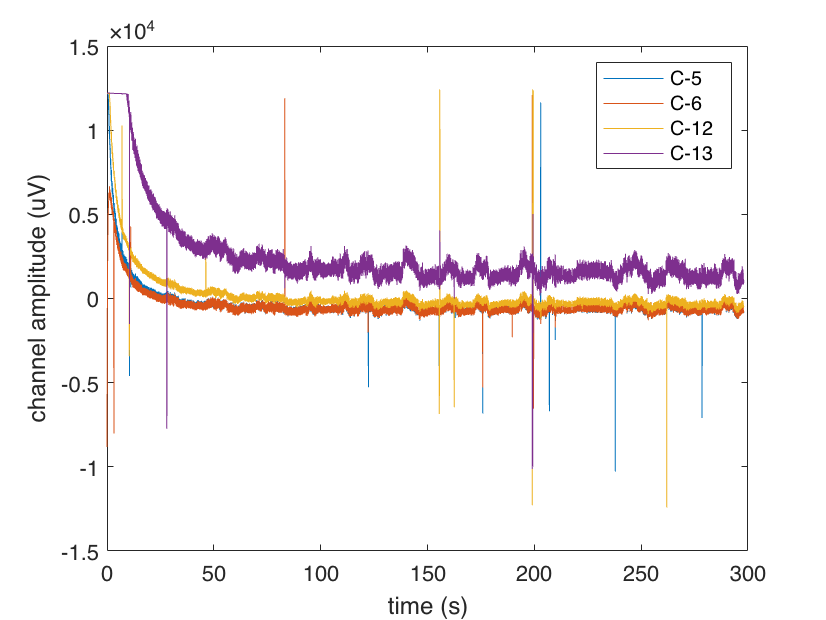

opts = detectImportOptions('/Users/sihanliang/Monkeylab/LFP/data/behaviors/bhv_1027/event_onset_1027.xlsx')

opts = setvartype(opts,["start","xEnd"],"datetime") 


ans = 	1.0e+04 *

    1.1726    1.1726    1.1726    1.1726    1.1726    1.1726    1.1726    1.1726    1.1726    1.1726    1.1727    1.1726    1.1726    1.1726    1.1726    1.1726    1.1727    1.1727    1.1726    1.1727    1.1726    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727    1.1727


opts = setvaropts(opts, ['start',"xEnd"], 'InputFormat', 'HH:mm:ss') % Specify the time format

ans = 包含以下字段的 struct :
              dataset: '/Users/sihanliang/monkeylab/LFP/data/EDF/data_aggregated/1030L00023_2023_11_16_11_03_55.edf'
           continuous: 'yes'
              channel: {4×1 cell}
            checkpath: 'pedantic'
             showlogo: 'yes'
    outputfilepresent: 'overwrite'
        tracktimeinfo: 'yes'
         trackmeminfo: 'yes'
              toolbox: [1×1 struct]
             callinfo: [1×1 struct]
              version: [1×1 struct]
               method: 'trial'
            removemcg: 'no'
            removeeog: 'no'
            precision: 'double'
              padding: 0
               paddir: 'both'
              montage: 'no'
           updatesens: 'no'
           dataformat: 'edf'
            dftfilter: 'no'
             lpfilter: 'no'
             hpfilter: 'no'
             bpfilter: 'no'
             bsfilter: 'no'
         medianfilter: 'no'
              padtype: 'data'
                reref: 'no'
           refchannel: {}
            refmethod:


eventData = readtable('/Users/sihanliang/Monkeylab/LFP/data/behaviors/bhv_1027/event_onset_1027.xlsx', opts)
eventData.Properties.VariableNames(2) = "end"

import recording excel file(recording start time for each channel)

opts2 = detectImportOptions('/Users/sihanliang/Monkeylab/LFP/data/behaviors/bhv_1027/recording_1027.xlsx')

opts =   SpreadsheetImportOptions - 属性:

   工作表 属性:
                        Sheet: ''

   替换 属性:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'

   变量导入 属性:
                VariableNames: {'start', 'xEnd'}
                VariableTypes: {'double', 'double'}
        SelectedVariableNames: {'start', 'xEnd'}
              VariableOptions: 显示所有 2 VariableOptions 
	使用 setvaropts/getvaropts 访问 VariableOptions 子属性
           VariableNamingRule: 'modify'

   范围 属性:
                    DataRange: 'A2' (Star

opts2 = setvartype(opts2,["start_time","end_time"],"datetime") 

opts =   SpreadsheetImportOptions - 属性:

   工作表 属性:
                        Sheet: ''

   替换 属性:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'

   变量导入 属性:
                VariableNames: {'start', 'xEnd'}
                VariableTypes: {'datetime', 'datetime'}
        SelectedVariableNames: {'start', 'xEnd'}
              VariableOptions: 显示所有 2 VariableOptions 
	使用 setvaropts/getvaropts 访问 VariableOptions 子属性
           VariableNamingRule: 'modify'

   范围 属性:
                    DataRange: 'A2' (


opts2 = setvaropts(opts2, ['start_time',"end_time"], 'InputFormat', 'HH:mm:ss') % Specify the time format

opts =   SpreadsheetImportOptions - 属性:

   工作表 属性:
                        Sheet: ''

   替换 属性:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'

   变量导入 属性:
                VariableNames: {'start', 'xEnd'}
                VariableTypes: {'datetime', 'datetime'}
        SelectedVariableNames: {'start', 'xEnd'}
              VariableOptions: 显示所有 2 VariableOptions 
	使用 setvaropts/getvaropts 访问 VariableOptions 子属性
           VariableNamingRule: 'modify'

   范围 属性:
                    DataRange: 'A2' (


recording = readtable('/Users/sihanliang/Monkeylab/LFP/data/behaviors/bhv_1027/recording_1027.xlsx', opts2)

eventData = 14×2 table
     start        xEnd  
    ________    ________

    12:52:53    12:52:58
    12:53:03    12:53:23
    12:56:16    12:56:27
    12:56:40    12:56:46
    12:58:09    12:58:14
    12:58:24    12:58:33
    12:58:42    12:59:05
    12:59:35    12:59:45
    13:02:07    13:02:17
    13:02:24    13:02:29
    13:02:46    13:02:51
    13:02:58    13:03:10
    13:03:21    13:03:26
    13:11:06    13:11:11


assign each event(symptom onset) to corresponding recording sessions/channels 

numrows = height(eventData)

eventData = 14×2 table
     start        end   
    ________    ________

    12:52:53    12:52:58
    12:53:03    12:53:23
    12:56:16    12:56:27
    12:56:40    12:56:46
    12:58:09    12:58:14
    12:58:24    12:58:33
    12:58:42    12:59:05
    12:59:35    12:59:45
    13:02:07    13:02:17
    13:02:24    13:02:29
    13:02:46    13:02:51
    13:02:58    13:03:10
    13:03:21    13:03:26
    13:11:06    13:11:11



eventData.channel = repmat("none", numrows, 1)
eventData.marker = repmat("0",numrows,1)

opts2 =   SpreadsheetImportOptions - 属性:

   工作表 属性:
                        Sheet: ''

   替换 属性:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'

   变量导入 属性:
                VariableNames: {'Channel', 'duration', 'start_time' ... and 2 more}
                VariableTypes: {'char', 'double', 'double' ... and 2 more}
        SelectedVariableNames: {'Channel', 'duration', 'start_time' ... and 2 more}
              VariableOptions: 显示所有 5 VariableOptions 
	使用 setvaropts/getvaropts 访问 VariableOption

for i = 1:numrows

opts2 =   SpreadsheetImportOptions - 属性:

   工作表 属性:
                        Sheet: ''

   替换 属性:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'

   变量导入 属性:
                VariableNames: {'Channel', 'duration', 'start_time' ... and 2 more}
                VariableTypes: {'char', 'double', 'datetime' ... and 2 more}
        SelectedVariableNames: {'Channel', 'duration', 'start_time' ... and 2 more}
              VariableOptions: 显示所有 5 VariableOptions 
	使用 setvaropts/getvaropts 访问 VariableOpti

    for j = 1:height(recording)
        if eventData.start(i) >= recording.start_time(j) && eventData.end(i) <= recording.end_time(j)
            eventData.channel(i) = recording.Channel(j); 
            eventData.marker(i) = recording.Channel_marker(j);

opts2 =   SpreadsheetImportOptions - 属性:

   工作表 属性:
                        Sheet: ''

   替换 属性:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'

   变量导入 属性:
                VariableNames: {'Channel', 'duration', 'start_time' ... and 2 more}
                VariableTypes: {'char', 'double', 'datetime' ... and 2 more}
        SelectedVariableNames: {'Channel', 'duration', 'start_time' ... and 2 more}
              VariableOptions: 显示所有 5 VariableOptions 
	使用 setvaropts/getvaropts 访问 VariableOpti

            break; 
        elseif eventData.start(i)>=recording.start_time(j) && eventData.end(i) >= recording.end_time(j) && eventData.start(i) <= recording.end_time(j)

recording = 4×5 table
           Channel            duration    start_time    end_time    Channel_marker
    ______________________    ________    __________    ________    ______________

    {'C-0 C-1 C-8 C-9 '  }       5         12:53:51     12:58:51          1       
    {'C-2 C-4 C-10 C-11' }       5         13:00:00     13:05:00          2       
    {'C-5 C-6 C-12 C-13 '}       5         13:05:30     13:10:30          3       
    {'C-0 C-1 C-14 C-15' }       5         13:11:20     13:16:20          4       


            eventData.channel(i) = recording.Channel(j);
            eventData.marker(i) = recording.Channel_marker(j);
            break;

numrows = 14

        elseif eventData.start(i)<= recording.start_time(j) && eventData.end(i) <= recording.end_time(j) && eventData.end(i) >= recording.start_time(j)
            eventData.channel(i) = recording.Channel(j);

eventData = 14×3 table
     start        end       channel
    ________    ________    _______

    12:52:53    12:52:58    "none" 
    12:53:03    12:53:23    "none" 
    12:56:16    12:56:27    "none" 
    12:56:40    12:56:46    "none" 
    12:58:09    12:58:14    "none" 
    12:58:24    12:58:33    "none" 
    12:58:42    12:59:05    "none" 
    12:59:35    12:59:45    "none" 
    13:02:07    13:02:17    "none" 
    13:02:24    13:02:29    "none" 
    13:02:46    13:02:51    "none" 
    13:02:58    13:03:10    "none" 
    13:03:21    13:03:26    "none" 
    13:11:06    13:11:11    "none" 


            eventData.marker(i) = recording.Channel_marker(j);

eventData = 14×4 table
     start        end       channel    marker
    ________    ________    _______    ______

    12:52:53    12:52:58    "none"      "0"  
    12:53:03    12:53:23    "none"      "0"  
    12:56:16    12:56:27    "none"      "0"  
    12:56:40    12:56:46    "none"      "0"  
    12:58:09    12:58:14    "none"      "0"  
    12:58:24    12:58:33    "none"      "0"  
    12:58:42    12:59:05    "none"      "0"  
    12:59:35    12:59:45    "none"      "0"  
    13:02:07    13:02:17    "none"      "0"  
    13:02:24    13:02:29    "none"      "0"  
    13:02:46    13:02:51    "none"      "0"  
    13:02:58    13:03:10    "none"      "0"  
    13:03:21    13:03:26    "none"      "0"  
    13:11:06    13:11:11    "none"      "0"  


            break;
        end
    end
end

eventData

eventData = 14×4 table
     start        end             channel          marker
    ________    ________    ___________________    ______

    12:52:53    12:52:58    "none"                  "0"  
    12:53:03    12:53:23    "none"                  "0"  
    12:56:16    12:56:27    "C-0 C-1 C-8 C-9 "      "1"  
    12:56:40    12:56:46    "C-0 C-1 C-8 C-9 "      "1"  
    12:58:09    12:58:14    "C-0 C-1 C-8 C-9 "      "1"  
    12:58:24    12:58:33    "C-0 C-1 C-8 C-9 "      "1"  
    12:58:42    12:59:05    "C-0 C-1 C-8 C-9 "      "1"  
    12:59:35    12:59:45    "none"                  "0"  
    13:02:07    13:02:17    "C-2 C-4 C-10 C-11"     "2"  
    13:02:24    13:02:29    "C-2 C-4 C-10 C-11"     "2"  
    13:02:46    13:02:51    "C-2 C-4 C-10 C-11"     "2"  
    13:02:58    13:03:10    "C-2 C-4 C-10 C-11"     "2"  
    13:03:21    13:03:26    "C-2 C-4 C-10 C-11"     "2"  
    13:11:06    13:11:11    "none"                  "0"  


Get events that occurred only within the first recording session

eventData = eventData(eventData.marker == "1",:)

eventData = 5×4 table
     start        end            channel          marker
    ________    ________    __________________    ______

    12:56:16    12:56:27    "C-0 C-1 C-8 C-9 "     "1"  
    12:56:40    12:56:46    "C-0 C-1 C-8 C-9 "     "1"  
    12:58:09    12:58:14    "C-0 C-1 C-8 C-9 "     "1"  
    12:58:24    12:58:33    "C-0 C-1 C-8 C-9 "     "1"  
    12:58:42    12:59:05    "C-0 C-1 C-8 C-9 "     "1"  


Get recording starting time for this session

recording_start_time = recording(recording.Channel_marker == 1,"start_time")

recording_start_time = table
    start_time
    __________

     12:53:51 


recording_start_time.start_time

ans = datetime
   12:53:51


convert event start/end time into seconds since the recording started and calculate the event durations

start_timestamps = seconds(eventData.start-recording_start_time.start_time)

start_timestamps =    145
   169
   258
   273
   291


end_timestamps = seconds(eventData.end - recording_start_time.start_time)

end_timestamps =    156
   175
   263
   282
   314



end_timestamps(find(end_timestamps >300)) = 300 % only account for the event duration within the recording session in case if events continued after the end of recording 

end_timestamps =    156
   175
   263
   282
   300


durations = end_timestamps - start_timestamps

durations =     11
     6
     5
     9
     9


% create the event structure
events = struct('type', {}, 'sample', {}, 'value', {}, 'duration', {}, 'offset', {});

% get the sampling rate
Fs = data.fsample; 

events_value = [1:length(durations)]

events_value =      1     2     3     4     5




% Loop through each event
for i = 1:length(start_timestamps)
    events(i).type = 'symptom onset';    % event name
    events(i).sample = round(start_timestamps(i) * Fs); % Convert onset time in seconds to sample number
    events(i).value = events_value(i);                % Value of the event marker 
    events(i).duration = round(durations(i) * Fs); % Duration of the event in samples
    events(i).offset = 0;               % 
end






events

events = 包含以下字段的 1×5 struct 数组:
    type
    sample
    value
    duration
    offset


% calculate the exact timepoints corresponding to each event and add to the events struct 
timepoints = data.time{1}

timepoints =          0    0.0024    0.0048    0.0072    0.0096    0.0120    0.0145    0.0169    0.0193    0.0217    0.0241    0.0265    0.0289    0.0313    0.0337    0.0361    0.0386    0.0410    0.0434    0.0458    0.0482    0.0506    0.0530    0.0554    0.0578    0.0602    0.0627    0.0651    0.0675    0.0699    0.0723    0.0747    0.0771    0.0795    0.0819    0.0843    0.0867    0.0892    0.0916    0.0940    0.0964    0.0988    0.1012    0.1036    0.1060    0.1084    0.1108    0.1133    0.1157    0.1181


event_start_index = [events.sample]

event_start_index =        60175       70135      107070      113295      120765


event_end_index = [events.sample]+[events.duration]

event_end_index =        64740       72625      109145      117030      124500



event_start_timepoints = timepoints(event_start_index)

event_start_timepoints =   144.9976  168.9976  257.9976  272.9976  290.9976


event_end_timepoints = timepoints(event_end_index)

event_end_timepoints =   155.9976  174.9976  262.9976  281.9976  299.9976


for i = 1:length(events)
    events(i).start_time = event_start_timepoints(i);
    events(i).end_time = event_end_timepoints(i);
end

events

events = 包含以下字段的 1×5 struct 数组:
    type
    sample
    value
    duration
    offset
    start_time
    end_time


add the event structure back to the data structure

data.event = events

data = 包含以下字段的 struct :
           hdr: [1×1 struct]
         label: {4×1 cell}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
         trial: {[4×124500 double]}
       fsample: 415
    sampleinfo: [1 124500]
           cfg: [1×1 struct]
         event: [1×5 struct]


events

events = 包含以下字段的 1×5 struct 数组:
    type
    sample
    value
    duration
    offset
    start_time
    end_time


Results: now the data structure attained a new field called "event", which contains info about times of the monkey's symptom onset. You will see the sample number, duration(in number of samples), start time and end time that correspond to each onset. 

Epoching data based on the symptom onsets

data_segments = {}
for i = 1: length(data.event)

    cfg = [];
    cfg.begsample = data.event(i).sample;


data_segments =

  空的 0×0 cell 数组



    cfg.endsample = data.event(i).sample + data.event(i).duration;
    data_segment = ft_redefinetrial(cfg, data);
    data_segments{i} = data_segment

end


the input is raw data with 4 channels and 1 trials


the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 1 MB


data_segments = 1×1 cell 数组
    {1×1 struct}


the input is raw data with 4 channels and 1 trials


the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB


data_segments = 1×2 cell 数组
    {1×1 struct}    {1×1 struct}


the input is raw data with 4 channels and 1 trials


the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB


data_segments = 1×3 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}


the input is raw data with 4 channels and 1 trials


the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB


data_segments = 1×4 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


the input is raw data with 4 channels and 1 trials


the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB


data_segments = 1×5 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Put the epoched data segments into one data structure for downstream analysis

cfg = [];
data_combined = ft_appenddata(cfg,data_segments{1},data_segments{2},data_segments{3},data_segments{4},data_segments{5})

concatenating over the "rpt" dimension


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 3 MB


data_combined = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [5×2 double]
         trial: {[4×4566 double]  [4×2491 double]  [4×2076 double]  [4×3736 double]  [4×3736 double]}
          time: {1×5 cell}
       fsample: 415
           cfg: [1×1 struct]


data_combined

data_combined = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [5×2 double]
         trial: {[4×4566 double]  [4×2491 double]  [4×2076 double]  [4×3736 double]  [4×3736 double]}
          time: {1×5 cell}
       fsample: 415
           cfg: [1×1 struct]


idea: 是不是也可以用ft_definetrial,然后上面自定义代码生成的event structure添加到输出的cfg structure中， 然后再用这个cfg structure进行 ft_redefinetrial?

以下是该方法的实验

cfg        = [];
cfg.dataset    = '1030L00023_2023_10_27_12_53_51.edf';
cfg.continuous = 'yes';
cfg.channel    = 'all';

data           = ft_preprocessing(cfg)

cfg = [];
cfg.dataset             = '1030L00023_2023_10_27_12_53_51.edf';
%cfg.trialdef.eventtype = 'symptom_onset';
%cfg.trialdef.eventvalue = {'1'};
cfg.trialdef.eventtype = '?';
cfg_symptom         = ft_definetrial(cfg);

manually update the trialdef, event info

failed.

Another Idea for segmenting data(best way! DONT RUN IT HERE. moved to the section after artifact removal）

event_start_sample = [data.event.sample]
event_end_sample = [data.event.sample] + [data.event.duration]

data.event.sample

trials = [event_start_sample',event_end_sample'];

event_start_sample =        60175       70135      107070      113295      120765


trials = [trials,zeros(length(event_end_sample),1)]

event_end_sample =        64740       72625      109145      117030      124500


cfg = [];

ans = 60175

ans = 70135

ans = 107070

ans = 113295

ans = 120765

cfg.trl = trials;
data_symptom_onset = ft_redefinetrial(cfg,data)
data_symptom_onset

trials =        60175       64740           0
       70135       72625           0
      107070      109145           0
      113295      117030           0
      120765      124500           0


data_symptom_onset.time

plot(data_symptom_onset.time{5},data_symptom_onset.trial{5})

work remained: using similar approach, segment data that corresponds to time periods without symptom.

the input is raw data with 4 channels and 1 trials


the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB


data_symptom_onset = 包含以下字段的 struct :
         label: {4×1 cell}
       fsample: 415
           cfg: [1×1 struct]
           hdr: [1×1 struct]
         trial: {[4×4566 double]  [4×2491 double]  [4×2076 double]  [4×3736 double]  [4×3736 double]}
          time: {1×5 cell}
    sampleinfo: [5×2 double]


2. Data preprocessing on raw continuous data(data filtering, artifact removal, etc.)

2.1 data filtering

*It is possible to apply filters to the data during the initial preprocessing/reading. It is also possible to apply filters afterwards by calling the *[***ft_preprocessing***](https://www.fieldtriptoolbox.org/reference/ft_preprocessing)* function with the data as second input argument*. Since above we've already read the raw continous data, here we choose the second option, 

possible filtering options:

- cfg.lpfilter      = 'no' or 'yes'  lowpass filter (default = 'no')

- %   cfg.hpfilter      = 'no' or 'yes'  highpass filter (default = 'no')

- %   cfg.bpfilter      = 'no' or 'yes'  bandpass filter (default = 'no')

- %   cfg.bsfilter      = 'no' or 'yes'  bandstop filter (default = 'no')

- %   cfg.dftfilter     = 'no' or 'yes'  line noise removal using discrete fourier transform (default = 'no')

- %   cfg.medianfilter  = 'no' or 'yes'  jump preserving median filter (default = 'no')

- %   cfg.lpfreq        = lowpass  frequency in Hz

- %   cfg.hpfreq        = highpass frequency in Hz

- %   cfg.bpfreq        = bandpass frequency range, specified as [lowFreq highFreq] in Hz

- %   cfg.bsfreq        = bandstop frequency range, specified as [low high] in Hz (or as Nx2 matrix for notch filter)

- %   cfg.dftfreq       = line noise frequencies in Hz for DFT filter (default = [50 100 150])

- %   cfg.lpfiltord     = lowpass  filter order (default set in low-level function)

- %   cfg.hpfiltord     = highpass filter order (default set in low-level function)

- %   cfg.bpfiltord     = bandpass filter order (default set in low-level function)

- %   cfg.bsfiltord     = bandstop filter order (default set in low-level function)

- %   cfg.lpfilttype    = digital filter type, 'but' or 'firws' or 'fir' or 'firls' (default = 'but')

- %   cfg.hpfilttype    = digital filter type, 'but' or 'firws' or 'fir' or 'firls' (default = 'but')

- %   cfg.bpfilttype    = digital filter type, 'but' or 'firws' or 'fir' or 'firls' (default = 'but')

- %   cfg.bsfilttype    = digital filter type, 'but' or 'firws' or 'fir' or 'firls' (default = 'but')

What we may need:

- low pass filter

- line noise filter for 50Hz and its harmonics(using bsfilter, specifying the band stop with a matrix, like cfg.bsfreq = [48 52]

- detrending?

First, we convert the signal to frequency domain and inspect the signal 

cfg              = [];

data_symptom_onset = 包含以下字段的 struct :
         label: {4×1 cell}
       fsample: 415
           cfg: [1×1 struct]
           hdr: [1×1 struct]
         trial: {[4×4566 double]  [4×2491 double]  [4×2076 double]  [4×3736 double]  [4×3736 double]}
          time: {1×5 cell}
    sampleinfo: [5×2 double]


cfg.output       = 'pow';
cfg.channel      = {'C-5'};

ans = 1×5 cell 数组
    {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 0.0795 0.0819 0.0843 0.0867 0.0892 0.0916 0.0940 0.0964 0.0988 0.1012 0.1036 0.1060 0.1084 0.1108 0.1133 0.1157 0.1181 0.1205 0.1229 0.1253 0.1277 0.1301 0.1325 0.1349 0.1373 0.1398 0.1422 0.1446 0.1470 0.1494 0.1518 0.1542 0.1566 0.1590 0.1614 0.1639 0.1663 0.1687 0.1711 0.1735 0.1759 0.1783 0.1807 0.1831 0.1855 0.1880 0.1904 0.1928 0.1952 0.1976 0.2000 0.2024 0.2048 0.2072 0.2096 0.2120 0.2145 0.2169 0.2193 0.2217 0.2241 0.2265 0.2289 0.2313 0.2337 0.2361 0.2386 0.2410 0.2434 0.2458 0.2482 0.2506 0.2530 0.2554 0.2578 0.2602 0.2627 0.2651 0.2675 0.2699 0.2723 0.2747 0.2771 0.2795 0.2819 0.2843 0.2867 0.2892 0.2916 0.2940 0.2964 0.2988 0.3012 0.3036 0.3060 0.3084 0.3108 0.3133 0.3157 0.3181 0.3205 0.3229 0.3253 0.3277 0.3301 0.3325 0.3349 0

cfg.method       = 'mtmfft';
cfg.taper        = 'hanning';
cfg.foilim          = [0.5 207.5];                         % analysis 2 to 30 Hz in steps of 2 Hz
                 % time window "slides" from -0.5 to 1.5 sec in steps of 0.05 sec (50 ms)
TFRhann = ft_freqanalysis(cfg, data);


data.label

ft_singleplotER(cfg,TFRhann)

Next, we try filtering

- band pass filter the maximum frequency range that can be recorded by 415hz sampling rate

- band pass filter the LFP frequency range (<100hz)

- filter out the line noise

%band pass frequencies between 0.5hz and 207.4 hz
cfg = [];
cfg.bpfilter = 'yes';
cfg.bpfreq = [0.5 207.4];
bandpassed_data = ft_preprocessing(cfg,data)


the input is raw data with 4 channels and 1 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 1/1 nfft: 123670 samples, datalength: 123670 samples, 1 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated 7 MB


Visually inspected the filtered data

cfg              = [];

ans = 4×1 cell 数组
    {'C-5' }
    {'C-6' }
    {'C-12'}
    {'C-13'}


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_singleplotER" took 0 seconds and required the additional allocation of an estimated 1 MB


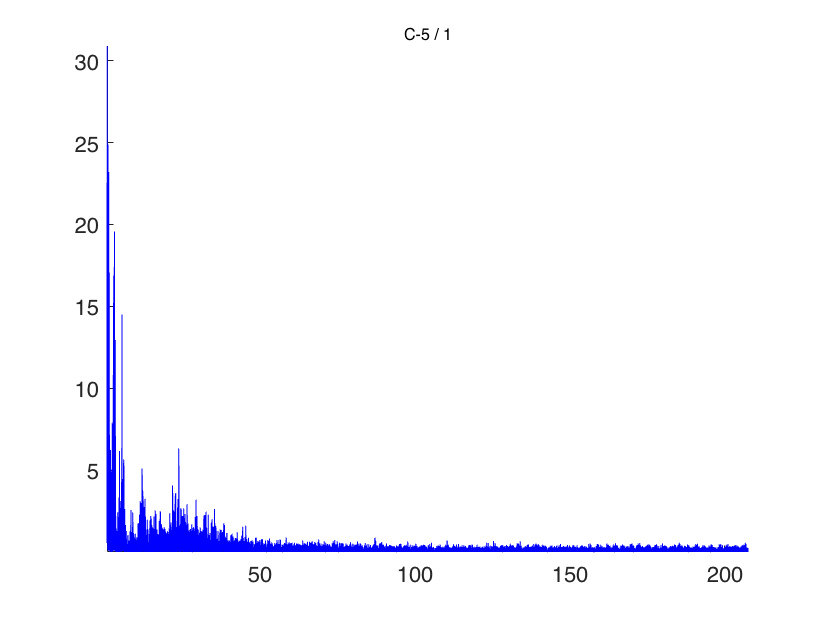

cfg.output       = 'pow';
cfg.channel      = {'C-5'};

cfg.method       = 'mtmfft';
cfg.taper        = 'hanning';
cfg.foilim          = [0.5 207.4];                         
                 
TFRhann = ft_freqanalysis(cfg, bandpassed_data);

cfg = [];

ft_singleplotER(cfg,TFRhann)

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 5 MB


bandpassed_data = 包含以下字段的 struct :
           hdr: [1×1 struct]
       fsample: 415
    sampleinfo: [1 123670]
         trial: {[4×123670 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
         label: {4×1 cell}
           cfg: [1×1 struct]


channel =1;

plot(bandpassed_data.time{1}, bandpassed_data.trial{1}(:, :))
xlim([38 40])
xlabel('time (s)')
ylabel('channel amplitude (uV)')
legend(data.label(channel))

Next, we band pass the traditionally considered LFP frequency range( < 100hz)

%band pass frequencies between 0.5hz and 100 hz

the input is raw data with 4 channels and 1 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 1/1 nfft: 123670 samples, datalength: 123670 samples, 1 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_singleplotER" took 0 seconds and required the additional allocation of an estimated 0 MB


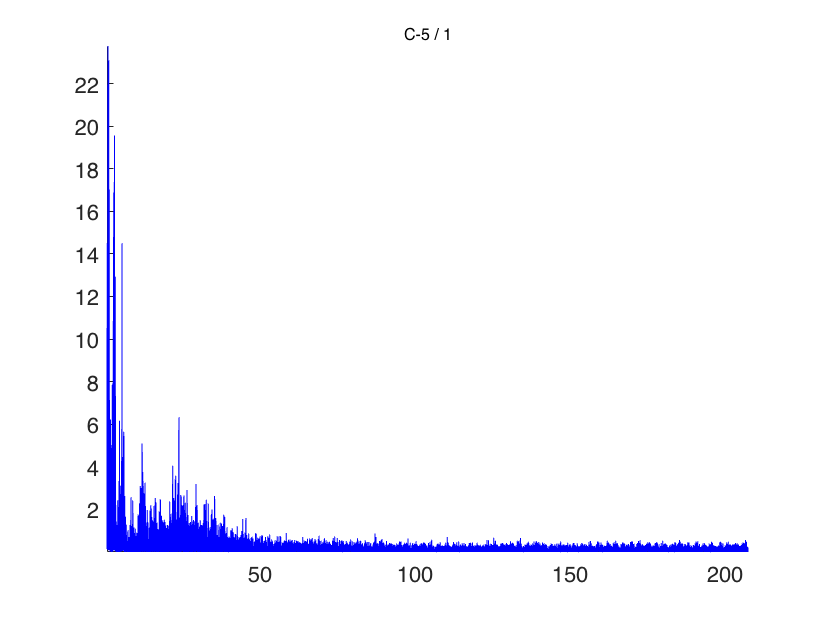

cfg = [];
cfg.bpfilter = 'yes';
cfg.bpfreq = [0.5 100];
bandpassed_data = ft_preprocessing(cfg,bandpassed_data)

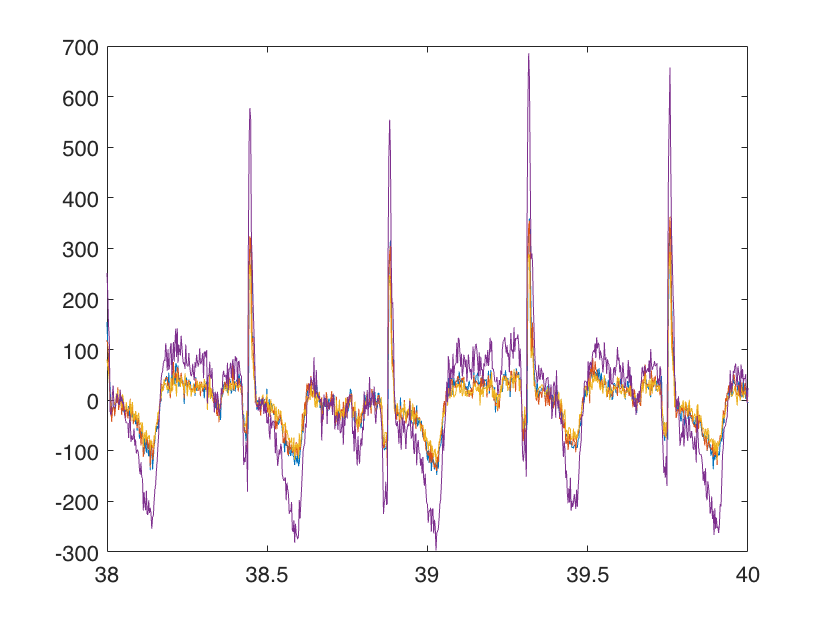

channel =1;

plot(bandpassed_data.time{1}, bandpassed_data.trial{1}(channel, :))
xlim([30 35])

xlabel('time (s)')
ylabel('channel amplitude (uV)')
legend(data.label(channel))

Next, we remove the line noise(50 Hz), here we use a bandstop filter, but literature suggests using template subtraction method better perserve the physiological signal at the line noise frequency

cfg = [];
cfg.bsfilter = 'yes';
cfg.bsfreq = [48 52;98 102];
bandpassed_data = ft_preprocessing(cfg,bandpassed_data)

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 4 MB


bandpassed_data = 包含以下字段的 struct :
           hdr: [1×1 struct]
       fsample: 415
    sampleinfo: [1 123670]
         trial: {[4×123670 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
         label: {4×1 cell}
           cfg: [1×1 struct]


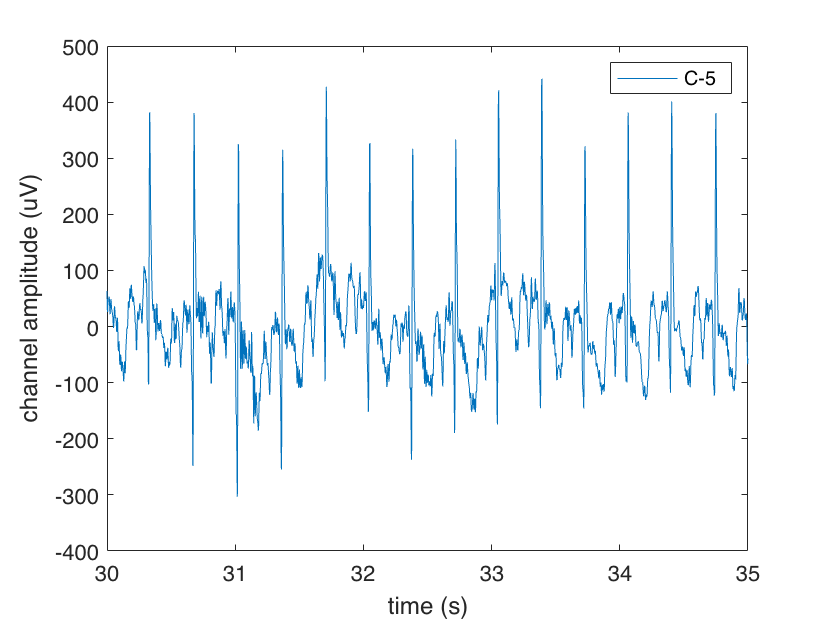

cfg              = [];
cfg.output       = 'pow';
cfg.channel      = {'C-5'};
cfg.method       = 'mtmfft';
cfg.taper        = 'hanning';
cfg.foilim          = [0.5 207];                         
                 

TFRhann = ft_freqanalysis(cfg, bandpassed_data);

cfg = [];

ft_singleplotER(cfg,TFRhann)


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 8 MB


bandpassed_data = 包含以下字段的 struct :
           hdr: [1×1 struct]
       fsample: 415
    sampleinfo: [1 123670]
         trial: {[4×123670 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
         label: {4×1 cell}
           cfg: [1×1 struct]


channel =1;

plot(bandpassed_data.time{1}, bandpassed_data.trial{1}(channel, :))
xlim([30 35])
xlabel('time (s)')
ylabel('channel amplitude (uV)')

legend(data.label(channel))

the input is raw data with 4 channels and 1 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 1/1 nfft: 123670 samples, datalength: 123670 samples, 1 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated 1 MB


2.2 Detrending

doesn't seem like a necessary step

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_singleplotER" took 0 seconds and required the additional allocation of an estimated 0 MB


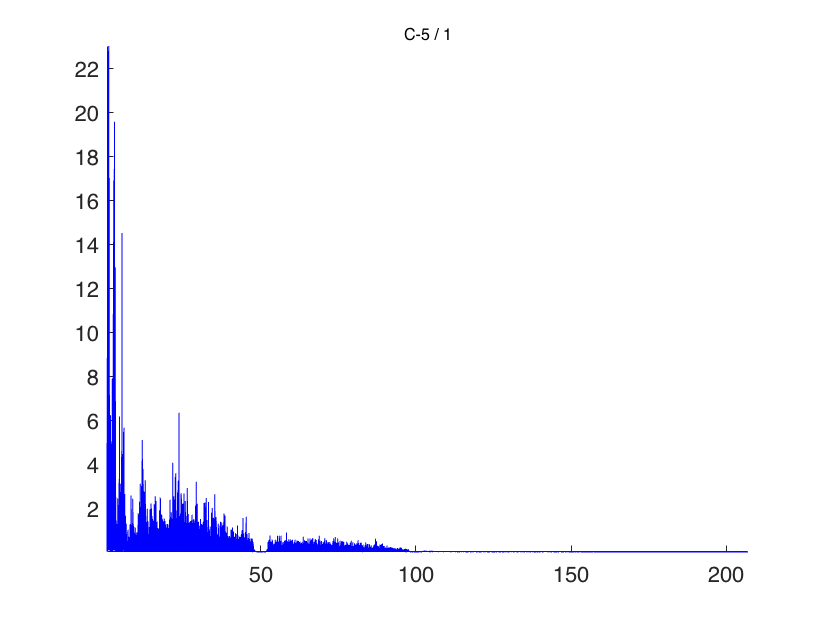

cfg = [];
cfg.detrend = 'yes';
detrended_bandpassed_data = ft_preprocessing(cfg,bandpassed_data)

channel =4;

plot(detrended_bandpassed_data.time{1}, detrended_bandpassed_data.trial{1}(channel, :))
xlim([10 20])
xlabel('time (s)')
ylabel('channel amplitude (uV)') 
legend(data.label(channel))

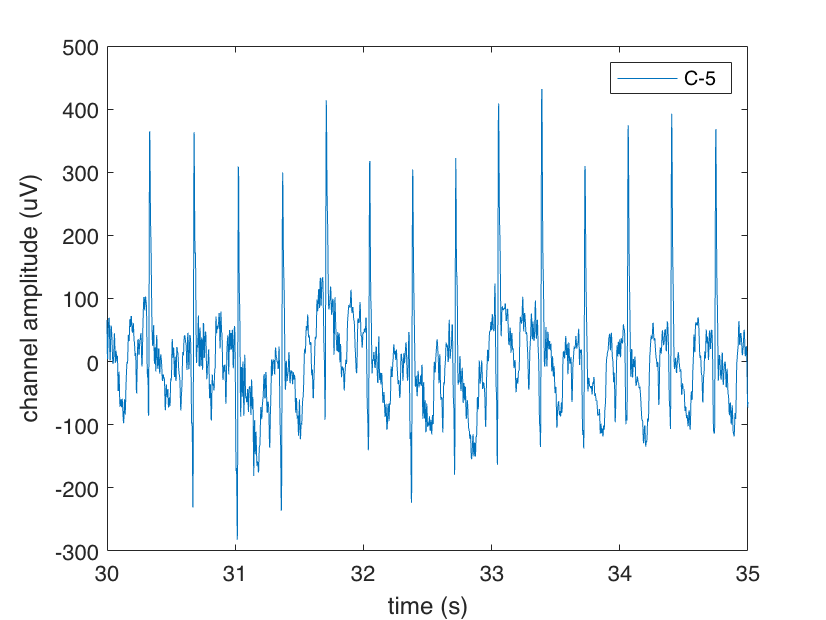

detrended_bandpassed_data

2.3 artifact removal(bad segments, bad channels, ECG, EOG, motion, muscle activity, etc)

2.3.1 bad segments

first, select channel first and remove bag segments for them individually,then add them back together using ft_appendata

Don't run the code below repeatedly. For future analysis, directly proceed to line 274 and load the cleaned data

data_list = {}

for i = 1:length(detrended_bandpassed_data.label)

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 3 MB


detrended_bandpassed_data = 包含以下字段的 struct :
           hdr: [1×1 struct]
       fsample: 415
    sampleinfo: [1 123670]
         trial: {[4×123670 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
         label: {4×1 cell}
           cfg: [1×1 struct]


    cfg = [];
    cfg.channel = detrended_bandpassed_data.label(i);
    data_list{i} = ft_preprocessing(cfg,detrended_bandpassed_data);
end


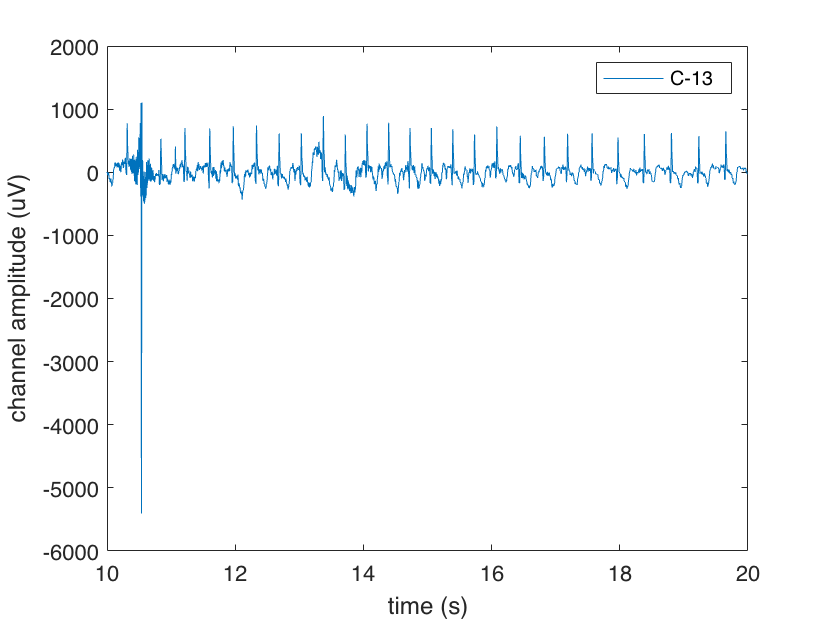


cfg = [];
cfg.viewmode = 'vertical'

cfg = ft_databrowser(cfg,data_list{1})


detrended_bandpassed_data = 包含以下字段的 struct :
           hdr: [1×1 struct]
       fsample: 415
    sampleinfo: [1 123670]
         trial: {[4×123670 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
         label: {4×1 cell}
           cfg: [1×1 struct]


cfg

cfg.artfctdef.reject = 'zero'


data_list =

  空的 0×0 cell 数组



data_list{1} = ft_rejectartifact(cfg,data_list{1})

cfg.artfctdef.visual.artifact

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an est

cfg = [];
cfg.viewmode = 'vertical'

cfg = 包含以下字段的 struct :
    viewmode: 'vertical'


cfg = ft_databrowser(cfg,data_list{2})

the input is raw data with 1 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-1134 1134]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

cfg.artfctdef.reject = 'zero'

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-1134 1134]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

data_list{2} = ft_rejectartifact(cfg,data_list{2})

cfg.artfctdef.visual.artifact

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-1134 1134]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

cfg = [];

detected   4 visual artifacts
rejected   0 trials completely
rejected   0 trials partially
filled parts of   0 trials with NaNs
filled parts of   1 trials with zeros
filled parts of   0 trials with a specified value
resulting   1 trials
the call to "ft_rejectartifact" took 0 seconds and required the additional allocation of an estimated 1 MB


data_list = 1×4 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


cfg.viewmode = 'vertical'
cfg = ft_databrowser(cfg,data_list{3})

ans =        15189       15429
       60548       60813
       68200       68712
      123246      123569


cfg.artfctdef.reject = 'zero'
data_list{3} = ft_rejectartifact(cfg,data_list{3})

cfg = 包含以下字段的 struct :
    viewmode: 'vertical'


cfg.artfctdef.visual.artifact

the input is raw data with 1 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:
------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  :

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-1190 1190]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

cfg = [];

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-1190 1190]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

cfg.viewmode = 'vertical'

detected   4 visual artifacts
rejected   0 trials completely
rejected   0 trials partially
filled parts of   0 trials with NaNs
filled parts of   1 trials with zeros
filled parts of   0 trials with a specified value
resulting   1 trials
the call to "ft_rejectartifact" took 0 seconds and required the additional allocation of an estimated 0 MB


data_list = 1×4 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


cfg = ft_databrowser(cfg,data_list{4})


ans =           28        1188
       43398       43621
       60539       60791
       68176       68614


cfg.artfctdef.reject = 'zero'
data_list{4} = ft_rejectartifact(cfg,data_list{4})

cfg = 包含以下字段的 struct :
    viewmode: 'vertical'


cfg.artfctdef.visual.artifact

the input is raw data with 1 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:
------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  :

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-1872 1872]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

cfg = [];

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-1872 1872]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

data_cleaned = ft_appenddata(cfg,data_list{1},data_list{2},data_list{3},data_list{4})

detected   5 visual artifacts
rejected   0 trials completely
rejected   0 trials partially
filled parts of   0 trials with NaNs
filled parts of   1 trials with zeros
filled parts of   0 trials with a specified value
resulting   1 trials
the call to "ft_rejectartifact" took 0 seconds and required the additional allocation of an estimated 0 MB


data_list = 1×4 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


cfg = [];

ans =            9        1152
       43310       43649
       60505       60879
       68106       68717
      104548      109526


cfg.viewmode = 'vertical'
cfg = ft_databrowser(cfg,data_cleaned)

save data_cleaned.mat

cfg = 包含以下字段的 struct :
    viewmode: 'vertical'


Directly load the cleaned data below. This data structure has been preprocessed with band pass filters,band stop filters and manual removal of bad segments.

load data_cleaned.mat

the input is raw data with 1 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:
------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  :

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-2020 2020]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

plot(data_cleaned.time{1},data_cleaned.trial{1})

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-2020 2020]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

data_cleaned

detected   0 visual artifacts
rejected   0 trials completely
rejected   0 trials partially
filled parts of   0 trials with NaNs
filled parts of   0 trials with zeros
filled parts of   0 trials with a specified value
resulting   1 trials
the call to "ft_rejectartifact" took 0 seconds and required the additional allocation of an estimated 0 MB


data_list = 1×4 cell 数组
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


2.3.2 ECG artifact removal

now we want to remove ECG(心电) artifact with ICA

apparantly there is problem with ICA since we have too limited channels and does not cover the entire brain unlike EEG

so we try other methods, including template subtraction, automatic artifact removal, QRS interpolation of the Perceive toolbox, adaptive filtering and singular value decomposition,SANTIA, and rereferencing.

First, we try rereferencing to neighboring channels, making the recording bipolar. Seems to work a bit. 

cfg = [];


ans =

  空的 0×2 double 矩阵



cfg.reref = 'yes'


Index exceeds the number of array elements. Index must not exceed 4.

cfg.refchannel    = {'C_0'};

data_reref = ft_preprocessing(cfg,data_cleaned)

concatenating over the "chan" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 3 MB


data_cleaned = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124500]
         trial: {[4×124500 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


channel =2;


cfg = 包含以下字段的 struct :
    viewmode: 'vertical'


plot(data_reref.time{1}, data_reref.trial{1}(channel, :))

the input is raw data with 4 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:
------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  :

cfg = 包含以下字段的 struct :
              viewmode: 'vertical'
            trackusage: '4D21ADF0'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-2020 2020]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'
             blocksize: 1
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'  'audiovideo'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1

xlim([100 102])
ylim([-400 400])
xlabel('time (s)')
ylabel('channel amplitude (uV)') 
legend(data.label(channel))

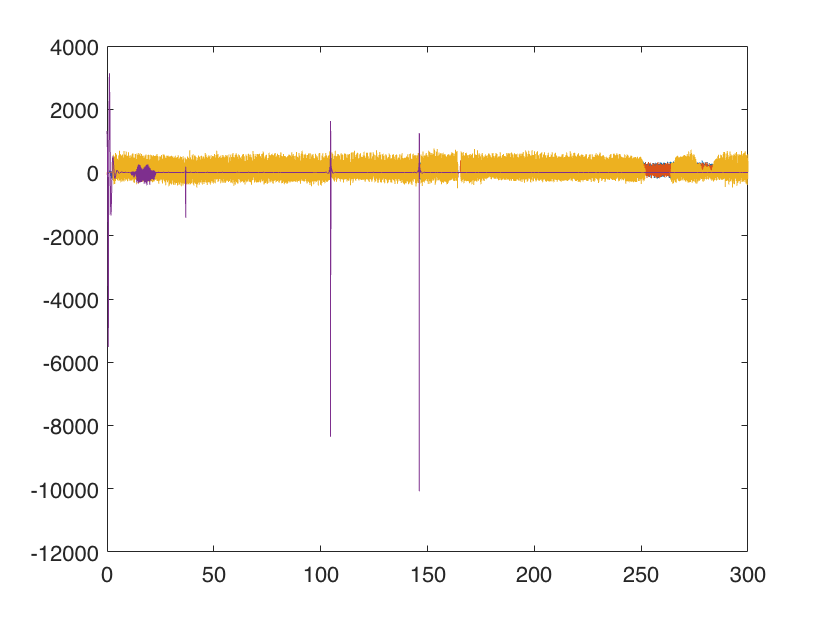

%compared with orig data
channel =2;


plot(data_cleaned.time{1}, data_cleaned.trial{1}(channel, :))

data_cleaned = 包含以下字段的 struct :
         label: {4×1 cell}
    sampleinfo: [1 124500]
         trial: {[4×124500 double]}
          time: {[0 0.0024 0.0048 0.0072 0.0096 0.0120 0.0145 0.0169 0.0193 0.0217 0.0241 0.0265 0.0289 0.0313 0.0337 0.0361 0.0386 0.0410 0.0434 0.0458 0.0482 0.0506 0.0530 0.0554 0.0578 0.0602 0.0627 0.0651 0.0675 0.0699 0.0723 0.0747 0.0771 … ]}
       fsample: 415
           cfg: [1×1 struct]


xlim([100 102])
ylim([-400 400])
xlabel('time (s)')
ylabel('channel amplitude (uV)') 
legend(data.label(channel))


cfg = [];
cfg.viewmode = 'vertical';
ft_databrowser(cfg,data_reref)

Next, we try template subtraction

%step 1: extract the data from channel c_0 and z-transformed
extracted_data = data_cleaned.trial{1}(1,:)
extracted_time = data_cleaned.time{1}
orig_data = extracted_data

zscored_lfp = zscore(extracted_data, 0, 2)



%visually inspect the peaks
Fs
start_time = 1; % Start time in seconds, adjust as needed
end_time = 10; % End time in seconds, adjust as needed
segment = zscored_lfp((start_time * Fs):(end_time * Fs))
time = extracted_time((start_time * Fs):(end_time * Fs))

plot(time,segment)

[peaks,locations] = findpeaks(segment,'MinPeakHeight', 2.5, 'MinPeakDistance', 50)
hold on 
plot(time(locations), peaks, 'rv', 'MarkerFaceColor', 'r')
hold off


%step 2: find the R-peaks

[peaks, locations] = findpeaks(zscored_lfp, 'MinPeakHeight', 2.5, 'MinPeakDistance', 50);

% Repeat for inverted signal
[peaks_neg, locations_neg] = findpeaks(-zscored_lfp, 'MinPeakHeight', 2, 'MinPeakDistance', 50);



plot(extracted_time,zscored_lfp)
hold on

plot(extracted_time(locations), peaks, 'rv', 'MarkerFaceColor', 'r')

plot(extracted_time(locations_neg), peaks_neg, 'rv', 'MarkerFaceColor', 'b')

xlim([120 130])
hold off


locations

%determine the orientation of the QRS complexes

% Calculate the average peak value for each orientation
avg_peak_value_normal = mean(peaks);
avg_peak_value_inverted = mean(peaks_neg);

% Check which orientation has the higher average peak value
if avg_peak_value_normal > avg_peak_value_inverted
    % Normal orientation has higher average, so QRS complexes are peaks
    qrs_orientation = 'normal'
else
    % Inverted orientation has higher average, so QRS complexes are troughs
    qrs_orientation = 'inverted'
end

% Additionally, check if a similar number of peaks are detected
if length(peaks) ~= length(peaks_neg)
    warning('Different number of peaks detected in the two orientations');
end





locations
extracted_time(locations)
mean(diff(locations))
mean(diff(extracted_time(locations)))
%we can see that on average the QRS complex occurs every 150 samples(RR interval~=0.36s/360ms). 
%Therefore,we know that the heart rate is about 167 beats /minutes. also,
%from literature we know that in macaque monkeys: 
%normal QRS = 51+-9.94ms, Heart rate = 134.8+-19.83,P wave = 33+-9.49
%T wave ~= 175, QT interval ~= 226, PR interval ~= 96



plot(extracted_time,extracted_data)
hold on 
plot(extracted_time(locations), peaks, 'rv', 'MarkerFaceColor', 'r')
xlim([40 50])
hold off






plot(extracted_time(Fs*60:Fs*62),extracted_data(Fs*60:Fs*62))


%step 3 generate QRS template
%epoching time windows around each QRS peak
%generate QRS template

qrs_length = 50; % in milliseconds
sample_qrs_length = round(qrs_length * Fs / 1000); % Convert ms to samples
epoch_length = 2 * sample_qrs_length + 1;
qrs_template = zeros(1, epoch_length);
lfp_epochs = zeros(length(locations),2 * sample_qrs_length + 1)

for i = 1:length(locations)
    epoch_start = max(locations(i) - sample_qrs_length, 1);
    epoch_end = min(locations(i) + sample_qrs_length, length(extracted_data));
    
    % Handle edge cases: pad with zeros if necessary
    epoch = zeros(1, epoch_length);
    actual_start = max(1, sample_qrs_length + 2 - locations(i));
    actual_end = actual_start + (epoch_end - epoch_start);
    
    epoch(actual_start:actual_end) = extracted_data(epoch_start:epoch_end);
    qrs_template = qrs_template + epoch;
    lfp_epochs(i, :) = epoch;

end
qrs_template = qrs_template / length(locations); % Average



%optimize qrs template

% Initialize parameters for lsqnonlin
initial_params = [1, 0]; % Start with scale=1 and offset=0

% Define options for lsqnonlin
options = optimoptions('lsqnonlin', 'Display', 'off','Algorithm','levenberg-marquardt');

% Preallocate for speed
optimized_params = zeros(size(lfp_epochs, 1), 2); % For storing scale and offset for each epoch

% Loop through each epoch in the LFP epochs array
for i = 1:size(lfp_epochs, 1)
    % Use the pre-created LFP epoch
    lfp_epoch = lfp_epochs(i, :);

    % Use lsqnonlin to optimize the template for this epoch
    [opt_params, ~] = lsqnonlin(@(params) error_function(params, lfp_epoch, qrs_template), ...
                                 initial_params, [], [], options); %modify here to switch between qrs and pqrst
    
    % Store the optimized parameters
    optimized_params(i, :) = opt_params;
    
    % Apply the optimized scale and offset to the PQRST template
    optimized_qrs_template = opt_params(1) * qrs_template + opt_params(2);
    
  
end




plot(optimized_qrs_template)
hold on
plot(qrs_template)
hold off

%now do the template subtraction based on the qrs template

%first we create a copy for the extracted data
qrs_cleaned_data = extracted_data
for i = 1:size(lfp_epochs, 1)


    % Define the start and end of the epoch in the original LFP data
    %epoch_start = max(locations(i) - sample_pqrst_length_before, 1);
    %epoch_end = min(locations(i) + sample_pqrst_length_after, length(extracted_data));
   
    %if you are using qrs template, then
    epoch_start = max(locations(i) - sample_qrs_length, 1);
    epoch_end = min(locations(i) + sample_qrs_length, length(extracted_data));
    
    % Subtract the optimized template from the LFP data
    
    qrs_cleaned_data(epoch_start:epoch_end) = extracted_data(epoch_start:epoch_end) - optimized_qrs_template(1:length(epoch_start:epoch_end));
end

%compare the results
plot(extracted_time, extracted_data)
xlim([160 162])
ylim([-200 400])

plot(extracted_time,qrs_cleaned_data)
xlim([160 162])
ylim([-200 400])

%给同事看一下处理情况，把清洗后的c0数据再导回原始data struct中，并进行格式转换和导出

data.trial{1}(1,:) = qrs_cleaned_data



hdr  = ft_fetch_header(data)

dat = data.trial{1};
ft_write_data('ECG_removed_c0.edf', dat, 'header', hdr)


%test reading the exported data
cfg        = [];
cfg.dataset    = 'ECG_removed_c0.edf';
cfg.continuous = 'yes';
cfg.channel    = 'all';

data_test           = ft_preprocessing(cfg)
cfg = [];
cfg.viewmode = 'vertical'
ft_databrowser(cfg,data_test)

%alterative approach by generating PQRST template
pqrst_length_before = 100; % milliseconds before the R-peak
pqrst_length_after = 300; % milliseconds after the R-peak
sample_pqrst_length_before = round(pqrst_length_before * Fs / 1000)
sample_pqrst_length_after = round(pqrst_length_after * Fs / 1000)
epoch_length = sample_pqrst_length_before + sample_pqrst_length_after + 1
pqrst_template = zeros(1, epoch_length);
lfp_epochs = zeros(length(locations),sample_pqrst_length_before+sample_pqrst_length_after+1)


for i = 1:length(locations)
    epoch_start = max(locations(i) - sample_pqrst_length_before, 1);
    epoch_end = min(locations(i) + sample_pqrst_length_after, length(extracted_data));

    % Handle edge cases by padding with zeros if necessary
    epoch = zeros(1, epoch_length); % Initialize the epoch with zeros
    actual_start = max(sample_pqrst_length_before - (locations(i) - epoch_start), 1);
    actual_end = actual_start + (epoch_end - epoch_start);
    
    epoch(actual_start:actual_end) = extracted_data(epoch_start:epoch_end);
    pqrst_template = pqrst_template + epoch; % Sum the epochs
    lfp_epochs(i, :) = epoch;
end
pqrst_template = pqrst_template / length(locations); % Average to create the template


%optimize pqrst template

% Initialize parameters for lsqnonlin
initial_params = [1, 0]; % Start with scale=1 and offset=0

% Define options for lsqnonlin
options = optimoptions('lsqnonlin', 'Display', 'off','Algorithm','levenberg-marquardt');

% Preallocate for speed
optimized_params = zeros(size(lfp_epochs, 1), 2); % For storing  scale and offset for each epoch

% Loop through each epoch in the LFP epochs array
for i = 1:size(lfp_epochs, 1)
    % Use the pre-created LFP epoch
    lfp_epoch = lfp_epochs(i, :);

    % Use lsqnonlin to optimize the template for this epoch
    [opt_params, ~] = lsqnonlin(@(params) error_function(params, lfp_epoch, pqrst_template), ...
                                 initial_params, [], [], options); 
    
    % Store the optimized parameters
    optimized_params(i, :) = opt_params;
    
    % Apply the optimized scale and offset to the PQRST template
    optimized_pqrst_template = opt_params(1) * pqrst_template + opt_params(2);
    
  
end

plot(pqrst_template)
hold on 
plot(optimized_pqrst_template)
hold off


%now we want to refine the template by cutting the irrelevant tails

p_wave_samples = round(33 * Fs / 1000)  % P wave in samples
qrs_samples = round(60 * Fs / 1000)     % QRS complex in samples
qt_interval_samples = round(226 * Fs / 1000) % QT interval in samples
t_wave_samples = qt_interval_samples - qrs_samples % T wave in samples
additional_margin = round(20 * Fs / 1000) % Additional margin in samples


% Convert durations to samples

p_wave_samples = round(33 * Fs / 1000); % P wave duration in samples
qt_samples = round(226 * Fs / 1000); % QT interval duration in samples
qrs_samples = round(51 * Fs / 1000); % QRS duration in samples

% Start and end of T wave in the template
t_wave_start = qt_samples - qrs_samples; % This assumes the Q wave starts at sample 1

% For the start of the P wave (assuming it starts at the beginning)
left_tail_start = 1
left_tail_end = p_wave_samples

% For the end of the T wave
right_tail_start = length(optimized_pqrst_template) - (qt_samples - t_wave_start)
right_tail_end = length(optimized_pqrst_template)


% Search window for minimal difference, set to a small portion of the P wave
search_window = round(p_wave_samples / 3)

% Left tail (beginning)
[~, min_diff_idx_left] = min(abs(diff(optimized_pqrst_template(left_tail_start:left_tail_end - search_window))))
min_diff_idx_left = min_diff_idx_left + left_tail_start

% Right tail (end)
[~, min_diff_idx_right] = min(abs(diff(optimized_pqrst_template(right_tail_start + search_window:right_tail_end))))
min_diff_idx_right = min_diff_idx_right + right_tail_start - 1 % account for the search window offset

% Equalize the template values at the start and end points
if optimized_pqrst_template(min_diff_idx_left) > optimized_pqrst_template(min_diff_idx_right)
    optimized_pqrst_template(min_diff_idx_right:end) = optimized_pqrst_template(min_diff_idx_left);
else
    optimized_pqrst_template(1:min_diff_idx_left) = optimized_pqrst_template(min_diff_idx_right);
end

% Trim the template to remove the flat tails
trimmed_optimized_pqrst_template = optimized_pqrst_template(min_diff_idx_left:min_diff_idx_right)

for i = 1:size(lfp_epochs, 1)

    % Define the start and end of the epoch in the original LFP data
    epoch_start = max(locations(i) - sample_pqrst_length_before, 1);
    epoch_end = min(locations(i) + sample_pqrst_length_after, length(extracted_data));
   
    % Subtract the optimized template from the LFP data
    
    pqrst_cleaned_data(epoch_start:epoch_end) = extracted_data(epoch_start:epoch_end) - optimized_pqrst_template(1:length(epoch_start:epoch_end));
end


plot(extracted_time,extracted_data)
xlim([60 62])


plot(extracted_time,pqrst_cleaned_data)
xlim([60 62])
ylim([-200 400])


plot(extracted_time,qrs_cleaned_data)
xlim([60 63])
ylim([-200 400])


SAVE pqrst cleaned data. proceed from here in the future

note that pqrst_cleaned_data is just a vector that stores the cleaned data of channel c_0. 

save pqrst_cleaned_data.mat

load pqrst_cleaned_data.mat


%暂时导出给同事看看

data.trial{1}(1,:) = pqrst_cleaned_data


hdr  = ft_fetch_header(data)

dat = data.trial{1};
ft_write_data('ECG_removed_c0_pqrst.edf', dat, 'header', hdr)


%test reading the exported data
cfg        = [];
cfg.dataset    = 'ECG_removed_c0_pqrst.edf';
cfg.continuous = 'yes';
cfg.channel    = 'all';

data_test           = ft_preprocessing(cfg)
cfg = [];
cfg.viewmode = 'vertical'
ft_databrowser(cfg,data_test)

Once decided which template to use, think about other potential preprocessing steps to increase the SNR ratio. Once finished all preprocessing steps, apply this complete procedure to all channels. 

%spectrogram on qrs_cleaned_data

data_test = data_cleaned

data_test.trial{1}(1,:) = pqrst_cleaned_data


cfg = [];
cfg.output       = 'pow';
cfg.channel      = {'C_0'};
cfg.method       = 'mtmfft';
cfg.taper        = 'hanning';
cfg.foilim          = [0.9,100];                         % analysis 2 to 30 Hz in steps of 2 Hz
                 % time window "slides" from -0.5 to 1.5 sec in steps of 0.05 sec (50 ms)
TFRhann = ft_freqanalysis(cfg, data_test);

%0.8Hz异常活跃


cfg = [];
ft_singleplotER(cfg,TFRhann)


plot(extracted_time, data_test.trial{1}(1,:))
xlim([10 12])
ylim([-200 400])

cfg = [];
cfg.viewmode = 'vertical'
ft_databrowser(cfg,data_test)


DATA SEGMENTATION

data_cleaned.trial{1}(1,:) = pqrst_cleaned_data


apparently the event markers field got lost accidentally during preprocessing, so we manually add it back.

data_cleaned.event = events


event_start_sample = [data_cleaned.event.sample]
event_end_sample = [data_cleaned.event.sample] + [data_cleaned.event.duration]

data.event.sample

trials = [event_start_sample',event_end_sample'];
trials = [trials,zeros(length(event_end_sample),1)]

cfg = [];
cfg.trl = trials;
data_seg_symptom = ft_redefinetrial(cfg,data_cleaned)
data_seg_symptom


plot(data_seg_symptom.time{1},data_seg_symptom.trial{1}(1,:))
xlim([5 6])


Now we segment the rest of the data(no symptom)

trials_new = trials(:,1:2)

sorted_times = sort(trials_new(:))

trials_rest = zeros(size(trials_new, 1)+1, 2)


if sorted_times(1) > 1
    trials_rest(1,:) = [1, sorted_times(1)-1]; % First interval without events
end

for i = 1:size(trials_rest, 1)-2
    trials_rest(i+1,:) = [sorted_times(2*i)+1, sorted_times(2*i+1)-1];
end

if sorted_times(end)< 124500
    trials_rest(end,:) = [sorted_times(end)+1, 124500];
end % Add an interval after the last event if the event < 124500

if trials_rest(end,:) == [0 0]
    trials_rest(end,:) = []
end

trials_rest(:,3) = 0

cfg = [];
cfg.trl = trials_rest;
data_seg_rest = ft_redefinetrial(cfg,data_cleaned)

data_seg_rest

Now we have two separate data structures that store the segmented LFP data corresponding to symptoms and no symptoms respectively. 

data_cleaned
data_seg_symptom
data_seg_rest


plot(data_seg_symptom.time{2},data_seg_symptom.trial{2}(1,:))


**ANALYSIS**

**questions：how to determine the proper length of frequency bin? what is the trade off between frequency resolution and ???(noise?)**

**how does the difference in length between seg_symptom and seg_rest affect the spectral analysis? should I segment the rest data to have similar length as seg_symptom? if so, how to choose which rest data to use and which to discard? **

**it seems like the symptom segment is much stronger in power. could it be resulted from the diffrence in signal length, the symptom segment is much shorter and therefore perserves much more noise? you should visualize the signals in time domain to see if there's any signs.**

**test code**

cfg         = [];
cfg.output  = 'pow';
cfg.channel = 'C_8';
cfg.method  = 'mtmfft';
cfg.taper   = 'hanning';
cfg.foi     = 0:1:50;
%cfg.pad = 1000


spectr_symptom  = ft_freqanalysis(cfg, data_seg_symptom)
spectr_rest = ft_freqanalysis(cfg,data_seg_rest)


figure
hold on;
plot(spectr_symptom.freq, (spectr_symptom.powspctrm), 'linewidth', 2)
plot(spectr_rest.freq, (spectr_rest.powspctrm), 'linewidth', 2)
legend('symptom', 'rest')
xlabel('Frequency (Hz)')
ylabel('Power (\mu V^2)')
hold off; 

spectr_symptom.freq
spectr_rest.freq

data_seg_rest
data_seg_symptom

plot(data_seg_rest.trial{4}(1,:))
ylim([-200 400])
plot(data_seg_symptom.trial{4}(1,:))
ylim([-200 400])


can I put the segmented data back together as continuous??

no

cfg = [];

cfg.continuous  = 'yes';              % force it to be continuous
data_continous_symptom_test        = ft_preprocessing(cfg,data_seg_symptom)

data_seg_symptom


what if I segment the symptom data into 1 s length segments?

cfg = [];
cfg.length = 1

test = ft_redefinetrial(cfg,data_seg_symptom)

test.trial{40}(end-100:end)




415*40



cat(2, data_seg_symptom.trial{:})
test.trial{1}


cfg         = [];
cfg.output  = 'pow';
cfg.channel = 'C_0';
cfg.method  = 'mtmfft';
cfg.taper   = 'hanning';
cfg.foi     = 0:2:100;
%cfg.pad = 1000


test_spectral  = ft_freqanalysis(cfg, test)
test_spectral2 = ft_freqanalysis(cfg,data_seg_symptom)



figure
hold on;
plot(test_spectral.freq, (test_spectral.powspctrm), 'linewidth', 2)
plot(test_spectral2.freq, (test_spectral2.powspctrm), 'linewidth', 2)

legend('1s', 'data_seg_symptom')
xlabel('Frequency (Hz)')
ylabel('Power (\mu V^2)')
hold off; 


function error = error_function(params, lfp_epochs, refined_pqrst_template)
scale = params(1);
offset = params(2);
optimized_template = scale * refined_pqrst_template + offset;
error = sum((lfp_epochs - optimized_template).^2);
end

